# Línea, Bola, Doble 01 - Generación de Datos

clear
clc 
close all

% rng('shuffle');
rng('default');
Nejemplos = 100;

## Bolas (tamaño variable)

imagenesBolas = cell(1,Nejemplos); 
puntosBolas = cell(1,Nejemplos);

for i = 1:Nejemplos 
    
    % Inicialización de imágenes
    imagenesBolas{i} = zeros(100,100);
    n = (randi(500) + 400);
    puntosBolas{i} = zeros(n,2);
    
    % Centro
    centre = [rand*100 rand*80 + 10];

    % Distribuciones normales en torno al centro, de sigma aleatorio
    sigma = rand*4 + 4;
    nd1 = makedist('normal', 'mu', centre(1), 'sigma', sigma);
    nd2 = makedist('normal', 'mu', centre(2), 'sigma', sigma);
    nd2 = truncate(nd2, 0, 100);
    
    
    
    % Generación de imágenes
    for j = 1:n
        
        % Posición del punto
        x = mod(random(nd1),100);
        y = random(nd2);
        puntosBolas{i}(j,:) = [x y]; 
        pos = ceil([100-y x]); %elige un punto al azar según una distribución normal en torno al centro
        
        imagenesBolas{i}(pos(1),pos(2)) = imagenesBolas{i}(pos(1),pos(2)) + 1;
    end
    
    imagenesBolas{i} = rescale(imagenesBolas{i});
end

## Dibujo de 16 figuras

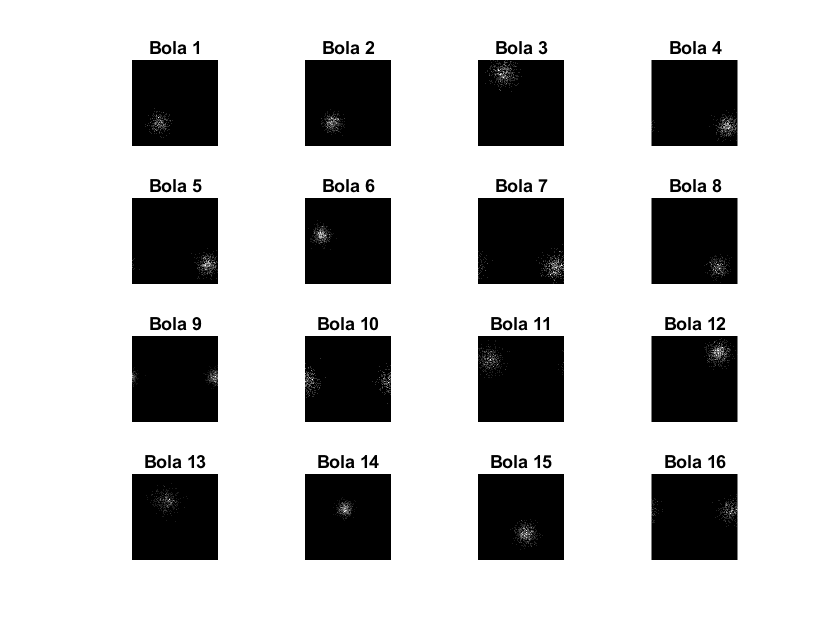

figure;
for i = 1:16
    subplot(4,4,i);
    imshow(imagenesBolas{randi(100)});
    title(['Bola ', num2str(i)]);
end

## Líneas

imagenesLineas = cell(1,Nejemplos); %100 ejemplos
puntosLineas = cell(1,Nejemplos);

for i = 1:Nejemplos 
    
    % Inicialización de imágenes    
    imagenesLineas{i} = zeros(100,100);
    n = (randi(800) + 400);
    puntosLineas{i} = zeros(n,2);
    
    % Centro
    centre = rand*80 + 10;
    
    % Distribuciones normales en torno al centro (eje)
    nd1 = makedist('normal', 'mu', centre(1), 'sigma',5);
    nd1 = truncate(nd1, 0, 100);
    
    % Generación de imágenes
    for j = 1:n
        
        % Posición del punto
        x = rand*100;
        y = mod(random(nd1),100);
        puntosLineas{i}(j,:) = [x y]; 
        pos = ceil([100-y x]);
       
        imagenesLineas{i}(pos(1),pos(2)) = imagenesLineas{i}(pos(1),pos(2)) + 1;

    end
    
    imagenesLineas{i} = rescale(imagenesLineas{i});
end

## Dibujo de 16 figuras

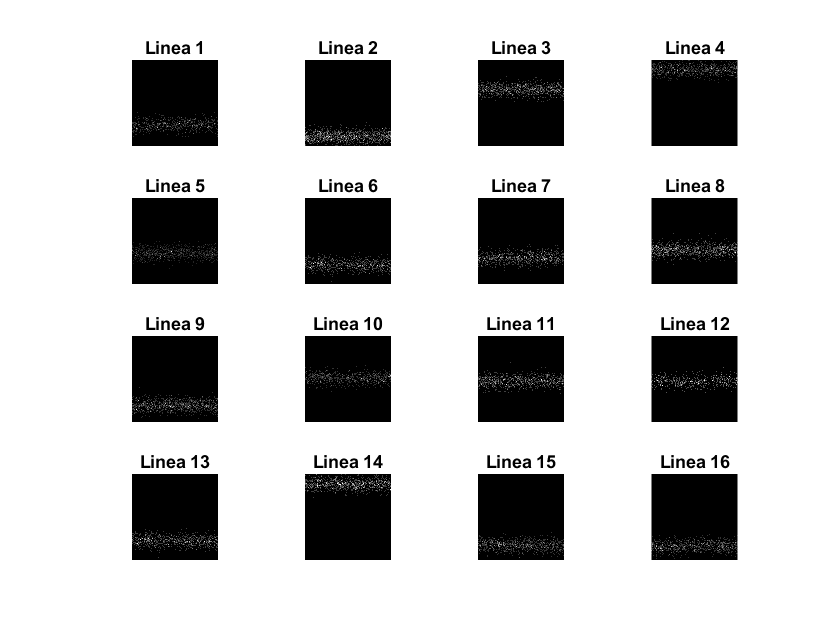

figure;
for i = 1:16
    subplot(4,4,i);
    imshow(imagenesLineas{randi(100)});
    title(['Linea ', num2str(i)]);
end

## Bolas dobles (tamaño variable)

imagenesDobles = cell(1,Nejemplos); 
puntosDobles = cell(1,Nejemplos);

for i = 1:Nejemplos 
    
    % Inicialización de imágenes
    imagenesDobles{i} = zeros(100,100);
    n = (randi(500) + 400);
    puntosDobles{i} = zeros(2*n,2);
    
    % Centro 1
    centre = [rand*100 rand*80 + 10];

    % Distribuciones normales en torno al centro 1, de sigma aleatorio
    sigma = rand*4 + 4;
    nd1 = makedist('normal', 'mu', centre(1), 'sigma', sigma);
    nd2 = makedist('normal', 'mu', centre(2), 'sigma', sigma);
    nd2 = truncate(nd2, 0, 100);
    
    % Generación de imágenes 1
    for j = 1:n
        
        % Posición del punto        
        x = mod(random(nd1),100);
        y = random(nd2);
        puntosDobles{i}(j,:) = [x y]; 
        pos = ceil([100-y x]);
        
        imagenesDobles{i}(pos(1),pos(2)) = imagenesDobles{i}(pos(1),pos(2)) + 1;

    end
    
    % Centro 2
    centre = mod(centre + [50 0],100);

    % Distribuciones normales en torno al centro 2, de sigma aleatorio
    nd1 = makedist('normal', 'mu', centre(1), 'sigma', sigma);
    nd2 = makedist('normal', 'mu', centre(2), 'sigma', sigma);
    nd2 = truncate(nd2, 0, 100);
    
    % Generación de imágenes
    for j = 1:n
        
        x = mod(random(nd1),100);
        y = random(nd2);
        puntosDobles{i}(j + n,:) = [x y]; 
        pos = ceil([100-y x]);
        

        imagenesDobles{i}(pos(1),pos(2)) = imagenesDobles{i}(pos(1),pos(2)) + 1;

    end
    
    
    imagenesDobles{i} = rescale(imagenesDobles{i});    
    
end

## Dibujo de 16 figuras

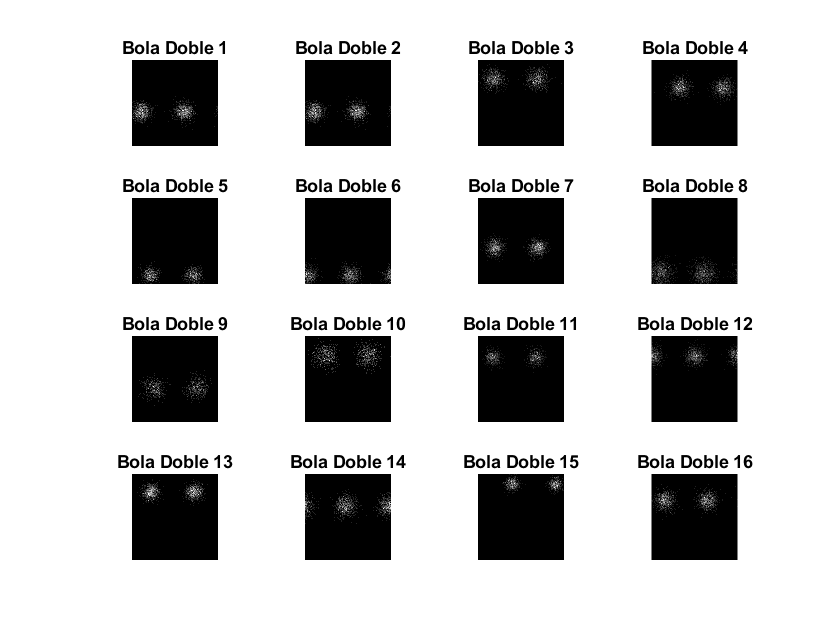

figure;
for i = 1:16
    subplot(4,4,i);
    imshow(imagenesDobles{randi(100)});
    title(['Bola Doble ', num2str(i)]);
end

## Salvar imágenes para clasificación

for i = 1:Nejemplos
    img = imagenesBolas{i};   
    str = strcat('.\imgLineaBolaDoble\Bola\Bola_', num2str(i), '.png');
    imwrite(img, str);
end

for i = 1:Nejemplos
    img = imagenesLineas{i};   
    str = strcat('.\imgLineaBolaDoble\Linea\Linea_', num2str(i), '.png');
    imwrite(img, str);
end

for i = 1:Nejemplos
    img = imagenesDobles{i};   
    str = strcat('.\imgLineaBolaDoble\Doble\Doble_', num2str(i), '.png');
    imwrite(img, str);
end

## Guardado de datos

save LBD_img imagenesBolas imagenesLineas imagenesDobles
save LBD_puntos puntosBolas puntosLineas puntosDobles Nejemplos